# Downloading and Preprocessing Data

### Obtaining Data from the SARB Web API

The South African Reserve Bank(SARB) hosts a large ammount of data from its database that can be accessed through their website, this includes data that they have collected as well as data obtained from other sources such as STATSA. They offer a Application Programming Interface(API) that facilitates the pulling of this data and graphs that they host on their website using various endpoints. 

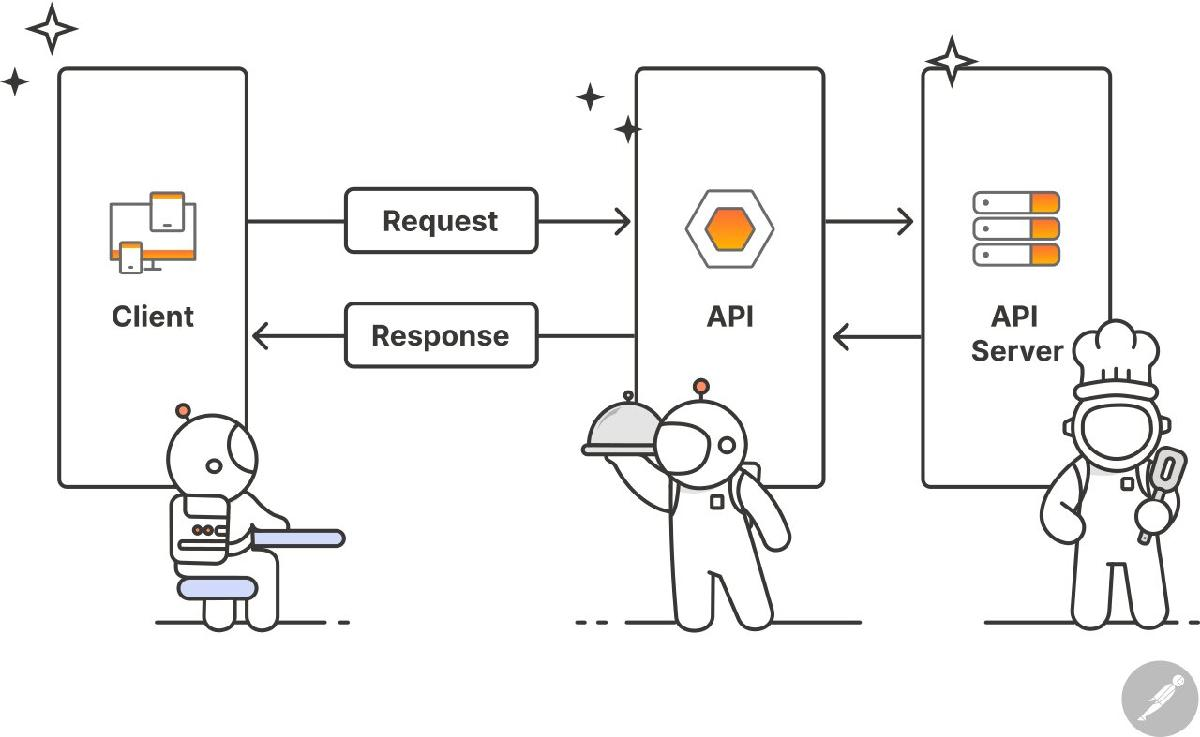

For this exercise, our data will be obtained from the Real Sector. The API can return complete tables with full account statements and the time series for each line item using the Time Series code(TsCode).

First we will need to **fetch the tables**

rb = ResBankEconData;
realSectorData = rb.retrieveData('RealSectorData');

       Id                           PageTitle                              TypeName           SectionId                                           SectionName                                             TsCode                      MeasureName                    TheValue            ValueDate           FormatNumber    FormatDate    SectionSequence    UnitOfMeasure    PublishingAgency                PercChange                PercChangeFormat
    _________    ________________________________________________    ____________________    ___________    _______________________________________________________________________________________    <s

head(realSectorData);

From the tables we can get the **time series code**(column TsCode) for the line items we want. Our modelling exercise will use Fixed Investment, Income(as wages) and consumption expenditure. From the table above these have the time series codes:

- NRI6009L - Gross domestic fixed investment (sa) 

- LABP130L - Wages/Earnings (sa)

- NRI6008L - Consumption expenditure by general government (sa)

With the time series codes, we can obtain more granular **time series data** from the API, here we must specify a start and end date, we'll be using data the last 18 years:

numyears =18;

numyears = 18

endDate = dateshift(datetime("today","Format","uuuu-MM-dd"), "start", "year", "current");
startDate = endDate - calyears(numyears);

investment = rb.getTimeSeries('NRI6009L', startDate, endDate);
income = rb.getTimeSeries('LABP130L', startDate, endDate);
expenditure = rb.getTimeSeries('NRI6008L', startDate, endDate);

head(investment);

            Period                           Timeseries                                                   Description                                      Value       FormatNumber    FormatDate
    _______________________    _______________________________________    ___________________________________________________________________________    __________    ____________    __________

    {'2022-12-31T00:00:00'}    {'Gross fixed capital formation (sa) '}    {'Gross fixed capital formation <br/> Current prices. Seasonally adjusted'}    9.8294e+05       {'0'}        {'Qq/yy'} 
    {'2022-09-30T00:00:00'}    {'Gross fixed capital formation (sa) '}    {'Gross fixed capital formation <br/> Current prices. Seasonally adjusted'}    9.5591e+05       {'0'}        {'Qq/yy'} 
    {'2022-06-30T00

### Preprocessing 

The data we get from the SARB data server is in a table format, it's easier to work in timetables so we will need to convert these, we also want to keep only the important columns from the time series tables which are the **Period** column and the** Values** column as and since our lowest frequency data is quartely we must ensure that this is consistent across all time tables.

investment = investment(:, ["Period" "Value"]);
income = income(:, ["Period" "Value"]);
expenditure = expenditure(:, ["Period" "Value"]);

investment.Period = datetime(investment.Period);
income.Period = datetime(income.Period);
income.Value = income.Value*10000; 
expenditure.Period = datetime(expenditure.Period);
 
income = table2timetable(income);
investment = table2timetable(investment);
expenditure = table2timetable(expenditure);

investment = retime(investment, 'quarterly', 'mean');
expenditure = retime(expenditure, 'quarterly', 'mean');
income = retime(income, 'quarterly', 'mean');

Once we have the cleaned the data, we can use MATLAB ready made preprocessing tools. For this example we need synchronise timetables task:

% Synchronize timetables
economicDataTimetable = synchronize(investment,expenditure,income,"union",...
    "fillwithmissing")

economicDataTimetable = 72×3 timetable
      Period       Value_investment    Value_expenditure    Value_income
    ___________    ________________    _________________    ____________

    01-Jan-2005       2.7247e+05          2.9035e+05         4.0846e+05 
    01-Apr-2005       2.8159e+05          2.9828e+05         4.1825e+05 
    01-Jul-2005       2.9849e+05          2.9627e+05         4.2853e+05 
    01-Oct-2005       3.1419e+05          3.0171e+05          4.347e+05 
    01-Jan-2006        3.272e+05          3.1417e+05           4.47e+05 
    01-Apr-2006       3.4223e+05          3.2625e+05         4.5069e+05 
    01-Jul-2006       3.6815e+05          3.2972e+05         4.6007e+05 
    01-Oct-2006       3.9167e+0

% renaming the columns 
cols = {'investment', 'expenditure', 'income'};
economicDataTimetable.Properties.VariableNames = cols;
head(economicDataTimetable, 10)

      Period       investment    expenditure      income  
    ___________    __________    ___________    __________

    01-Jan-2005    2.7247e+05    2.9035e+05     4.0846e+05
    01-Apr-2005    2.8159e+05    2.9828e+05     4.1825e+05
    01-Jul-2005    2.9849e+05    2.9627e+05     4.2853e+05
    01-Oct-2005    3.1419e+05    3.0171e+05      4.347e+05
    01-Jan-2006     3.272e+05    3.1417e+05       4.47e+05
    01-Apr-2006    3.4223e+05    3.2625e+05     4.5069e+05
    01-Jul-2006    3.6815e+05    3.2972e+05     4.6007e+05
    01-Oct-2006    3.9167e+05    3.3526e+05     4.7682e+05
    01-Jan-2007    4.2313e+05    3.5869e+05     4.7245e+05
    01-Apr-2007    4.4035e+05     3.596e+05 

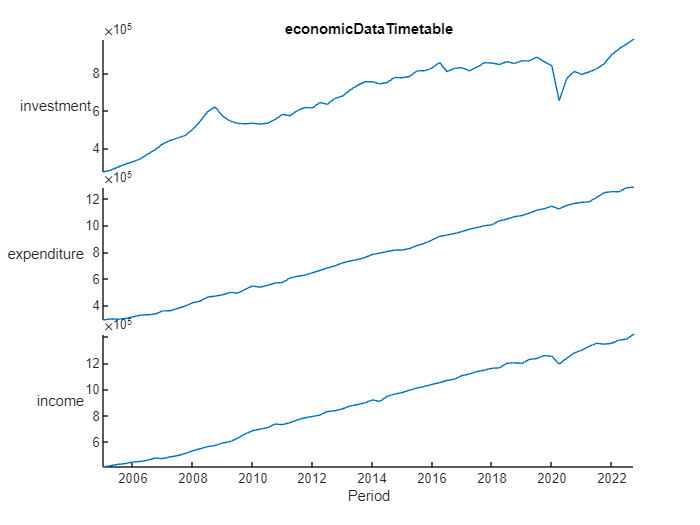

% Create stackedplot of economicDataTimetable
h = stackedplot(economicDataTimetable);

% Add title
title("economicDataTimetable")